% 주어진 데이터
temperature = [10, 20, 30]; % 온도 데이터
amplitude = [3.8, 2.1, 5.1]; % 진폭 데이터

% Fitting을 위한 함수 모델 정의
fun = @(x, t) x(1) * exp(x(2) * t); % 사용할 함수 모델 (지수 함수)

% 초기 추정 파라미터 설정
x0 = [1, 0]; % 초기 파라미터 추정값

% Fitting 수행
x = lsqcurvefit(fun, x0, temperature, amplitude);


국소 최솟값이 있을 수 있습니다.

제곱합의 초기값 대비 최종 변화가 함수 허용오차의 
값보다 작기 때문에 lsqcurvefit이(가) 중지되었습니다.

<중지 기준 세부 정보>



% 결과 출력
disp('Fitting 결과:');

Fitting 결과:


disp(['파라미터 x1 = ' num2str(x(1))]);

파라미터 x1 = 2.2837


disp(['파라미터 x2 = ' num2str(x(2))]);

파라미터 x2 = 0.022648


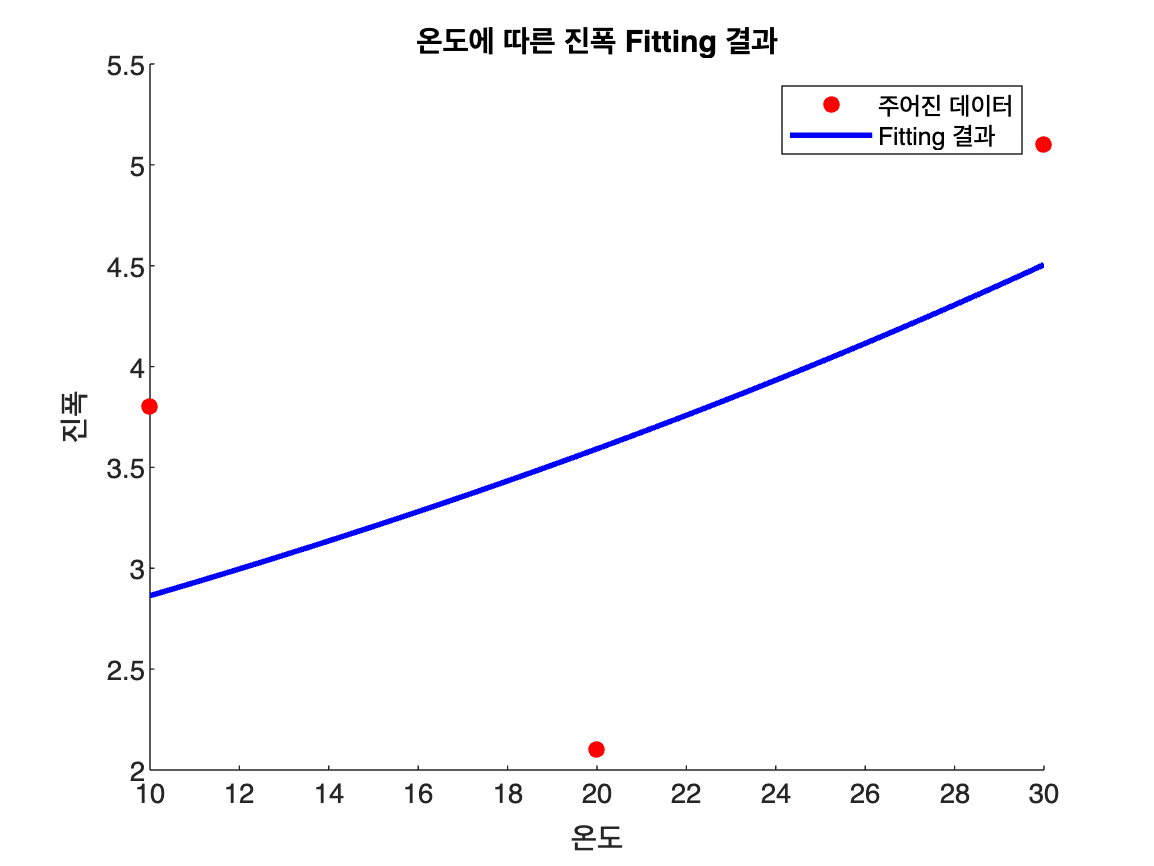


% Fitting 결과 그래프 플로팅
t = linspace(min(temperature), max(temperature), 100); % 플롯을 위한 온도 범위 설정
fitted_amplitude = fun(x, t); % fitting된 함수에 대한 진폭 계산

figure;
scatter(temperature, amplitude, 'ro', 'filled'); % 주어진 데이터 포인트 플롯
hold on;
plot(t, fitted_amplitude, 'b-', 'LineWidth', 2); % fitting된 함수 그래프 플롯
hold off;
legend('주어진 데이터', 'Fitting 결과');
xlabel('온도');
ylabel('진폭');
title('온도에 따른 진폭 Fitting 결과');

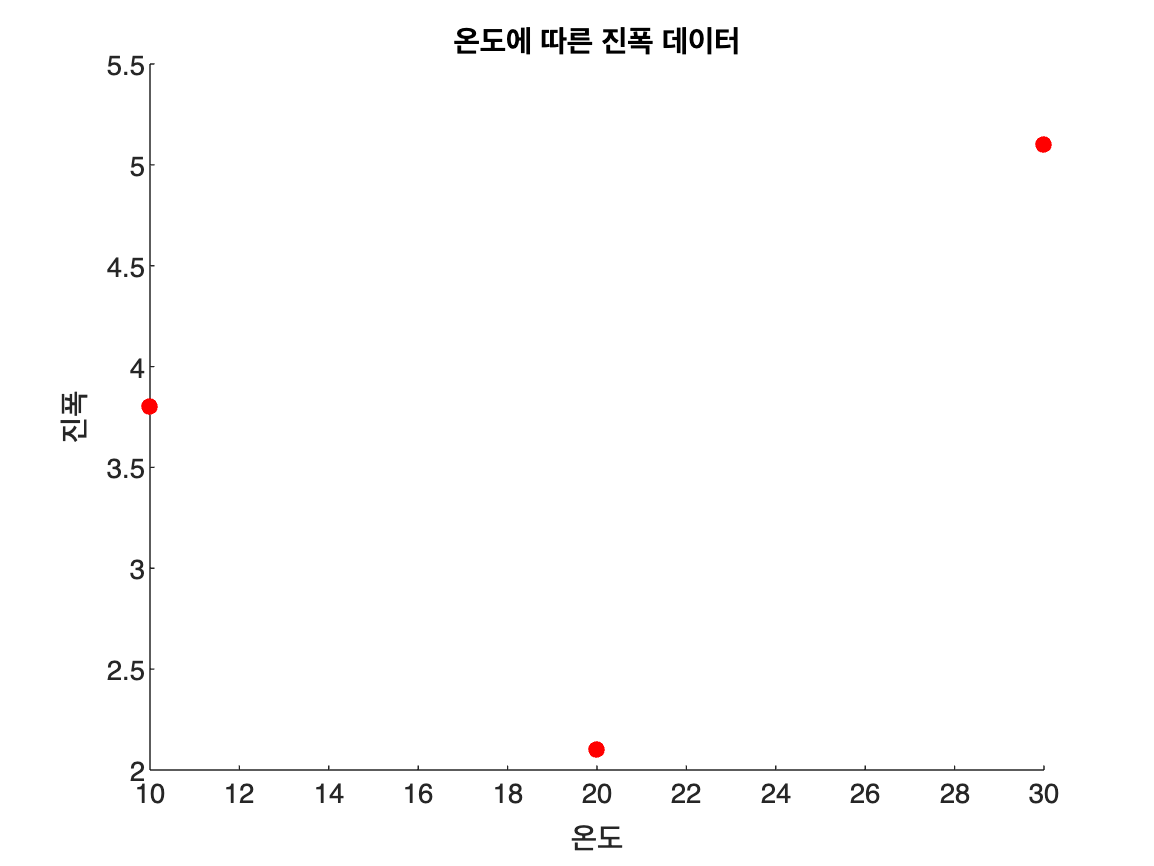


% 주어진 데이터
temperature = [10, 20, 30]; % 온도 데이터
amplitude = [3.8, 2.1, 5.1]; % 진폭 데이터

% 데이터 시각화
scatter(temperature, amplitude, 'ro', 'filled');
xlabel('온도');
ylabel('진폭');
title('온도에 따른 진폭 데이터');


% 데이터에 대한 특징 파악
% 예를 들어, 주어진 데이터가 증가하는 경향을 보이는 경우,
% 다항식 모델 (예: 다항식의 차수를 조정하여 적합한 차수 선택)
% 또는 지수 함수 모델 등을 고려할 수 있습니다.

% 다항식 모델로 fitting (2차 다항식 예시)
degree = 2; % 다항식의 차수
coefficients = polyfit(temperature, amplitude, degree); % 다항식 fitting
fitted_amplitude = polyval(coefficients, temperature); % fitting된 다항식에 대한 진폭 계산

% 결과 출력
disp('Fitting 결과:');

Fitting 결과:


disp(['다항식 차수: ' num2str(degree)]);

다항식 차수: 2


disp(['다항식 계수: ' num2str(coefficients)]);

다항식 계수: 0.0235       -0.875         10.2


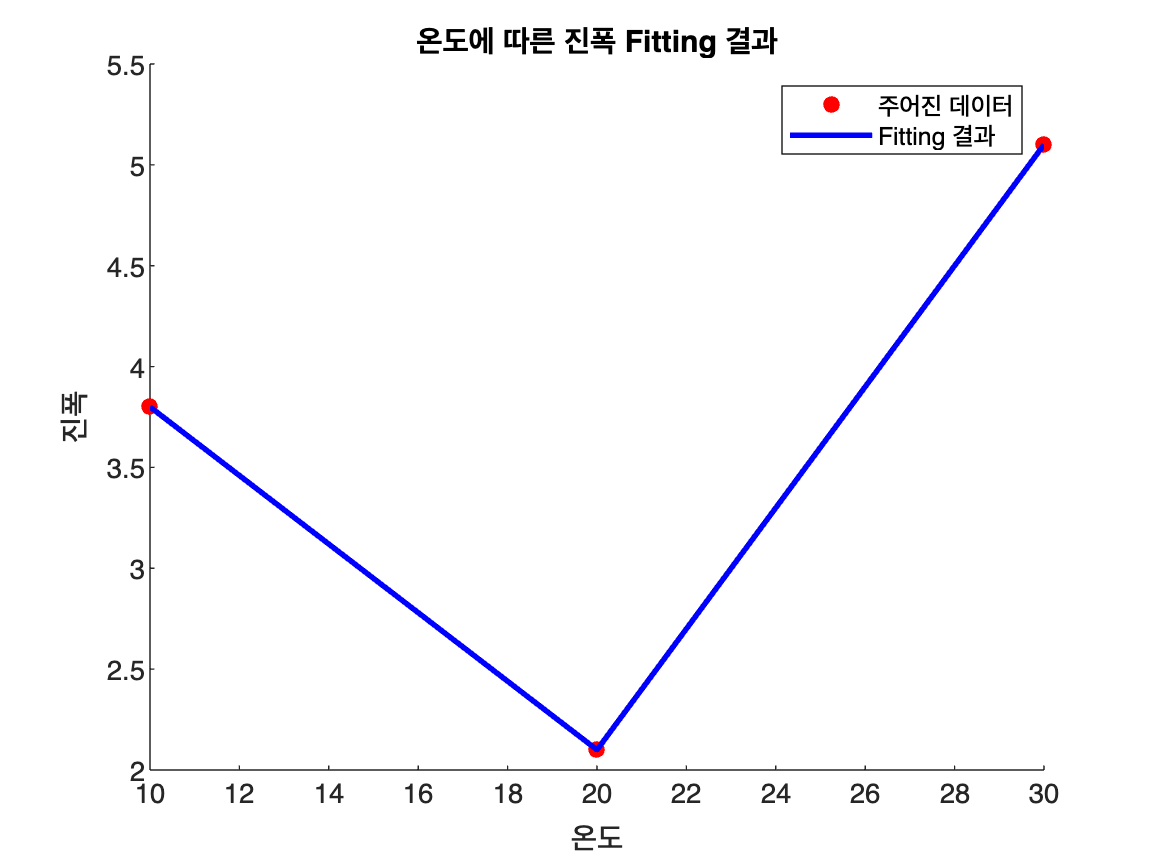


% Fitting 결과 그래프 플로팅
figure;
scatter(temperature, amplitude, 'ro', 'filled');
hold on;
plot(temperature, fitted_amplitude, 'b-', 'LineWidth', 2);
hold off;
legend('주어진 데이터', 'Fitting 결과');
xlabel('온도');
ylabel('진폭');
title('온도에 따른 진폭 Fitting 결과');

% 주어진 데이터
temperature = [10, 20, 30]; % 온도 데이터
amplitude = [3.8, 2.1, 5.1]; % 진폭 데이터
amplitude2 = [2.1, 3.1, 5.1]; % 진폭 데이터

% 데이터 시각화
scatter(temperature, amplitude, 'ro', 'filled');
xlabel('온도');
ylabel('진폭');
title('온도에 따른 진폭 데이터');


% 데이터에 대한 특징 파악
% 주어진 데이터의 경향을 고려하여 적합한 차수 선택

% 다항식 모델로 fitting (3차 다항식 예시)
degree = 3; % 다항식의 차수
coefficients = polyfit(temperature, amplitude, degree); % 다항식 fitting


coefficients2 = polyfit(temperature, amplitude2, degree); % 다항식 fitting

fitted_amplitude = polyval(coefficients, temperature); % fitting된 다항식에 대한 진폭 계산
fitted_amplitude2 = polyval(coefficients2, temperature); % fitting된 다항식에 대한 진폭 계산

% 결과 출력
disp('Fitting 결과:');

Fitting 결과:


disp(['다항식 차수: ' num2str(degree)]);

다항식 차수: 3


disp(['다항식 계수: ' num2str(coefficients)]);

다항식 계수: 0.0017     -0.0785       0.995           0


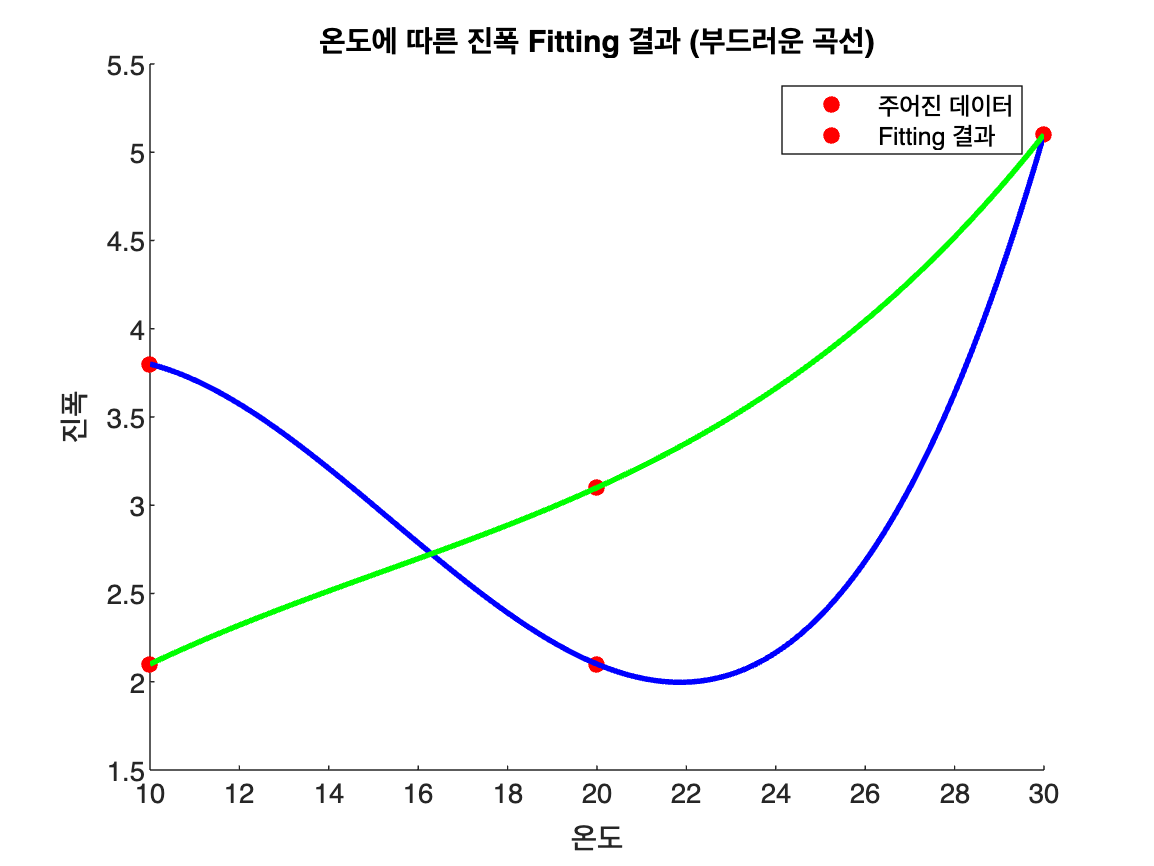


% Fitting 결과 그래프 플로팅
figure;
scatter(temperature, amplitude, 'ro', 'filled');
hold on;
scatter(temperature, amplitude2, 'ro', 'filled');

t = linspace(min(temperature), max(temperature), 100); % 부드러운 곡선을 위한 추가 데이터 포인트 생성
fitted_amplitude_smooth = polyval(coefficients, t); % 추가 데이터에 대한 fitting된 다항식에 대한 진폭 계산
fitted_amplitude_smooth2 = polyval(coefficients2, t); % 추가 데이터에 대한 fitting된 다항식에 대한 진폭 계산

plot(t, fitted_amplitude_smooth, 'b-', 'LineWidth', 2);
plot(t, fitted_amplitude_smooth2, 'g-', 'LineWidth', 2);

hold off;
legend('주어진 데이터', 'Fitting 결과');
xlabel('온도');
ylabel('진폭');
title('온도에 따른 진폭 Fitting 결과 (부드러운 곡선)');